# HexaMotor — Advanced Demo: Lead-Lag Compensation of the Position Loop

*Continues *`HexaMotor_SysID_Demo`*: the motor model identified there (saved as *`HexaMotorModel`* in the workspace and *`HexaMotorModel.mat`*) is used to design a PD controller and then a lead compensator, following the "Position Control V02" manual (sections 2.2, 2.3, 3.5, 3.6).*

- Take the identified motor $G(s) = \frac{k_m}{\tau s + 1}$.

- Design the **PD** position controller from the canonical second-order specs ($\%OS$, $T_p$).

- Design a **lead** compensator that raises the phase margin to 60°, including the 200 Hz discretization.

- **Run** step and chirp experiments on `HexaMotor_LeadLag_Control_V02.slx` with the model's `Kp`, `Kd`, `T1` and `T2` set automatically.

- Compare PD against PD + Lead: step responses, the frequency responses and the Bode shift.

## 0. Demo settings

- **Virtual motor** — the experiments run on the built-in nonlinear motor emulator (no hardware needed).

- **Hardware** — the experiments run on the HexaMotor (Arduino MKR Zero, Monitor & Tune / external mode). While each run executes, the Simulink model and its Scope open beside the Live Editor and the Scope streams the reference and response live from the board.

runMode = "sim";
OS_PD = 25;
Tp_PD = 0.15;
PM_target = 60;

fs = 200; Ts = 1/fs;
sampleRate = Ts;                  % used by the Simulink model (a sample TIME)
N = 100;                          % derivative filter coefficient of the model's PD block
llModel = "HexaMotor_LeadLag_Control_V02";
s = tf('s'); z = tf('z', Ts);
if runMode == "hw", measLabel = "Measured"; else, measLabel = "Emulated"; end

% --- motor model from Demo 1: workspace first, then HexaMotorModel.mat, else identify from the recording ---
if exist("HexaMotorModel", "var") && isstruct(HexaMotorModel)
    modelSource = "workspace (" + HexaMotorModel.source + ")";
elseif isfile("HexaMotorModel.mat")
    load("HexaMotorModel.mat", "HexaMotorModel");
    modelSource = "HexaMotorModel.mat (" + HexaMotorModel.source + ", " + string(HexaMotorModel.created) + ")";
else
    rec = load("FrequencyResponse.mat", "ScopeData");
    d = rec.ScopeData;
    Tcl = tfest(iddata(d.signals.values(:,2), d.signals.values(:,1), median(diff(d.time))), 2, 0);
    den = Tcl.Denominator/Tcl.Denominator(1);
    HexaMotorModel = struct("km", den(3)/den(2)/10, "tau", 1/den(2), ...  % recording made with Kp = 10
        "source", "FrequencyResponse.mat - run HexaMotor_SysID_Demo first to use your own identification");
    modelSource = HexaMotorModel.source;
end
km = HexaMotorModel.km; tau = HexaMotorModel.tau;
G = km/(tau*s + 1);                               % voltage -> velocity
P = G/s;                                          % voltage -> position
Pd = c2d(P, Ts, "zoh");                           % what the 200 Hz controller sees
fprintf("Motor model (%s):  G(s) = %.3f / (%.4f s + 1)\n", modelSource, km, tau);

Motor model (workspace (HexaMotor_SysID_Demo, mode rec)):  G(s) = 2.494 / (0.0810 s + 1)


## 1. PD design from canonical second-order specs

With $PD(s) = K_p + K_ds$ and $P(s) = \frac{k_m}{s(\tau s+1)}$:


$$T_1(s) = \frac{k_m(K_ds + K_p)}{\tau s^2 + (1 + k_mK_d)s + k_mK_p} \quad\Rightarrow\quad \omega_n^2 = \frac{k_mK_p}{\tau}, \qquad 2\zeta\omega_n = \frac{1 + k_mK_d}{\tau}$$



$$K_p = \frac{\omega_n^2\tau}{k_m}, \qquad K_d = \frac{2\zeta\omega_n\tau - 1}{k_m}, \qquad \zeta = \frac{-\ln(OS)}{\sqrt{\pi^2+\ln^2(OS)}}, \qquad \omega_n = \frac{\pi}{T_p\sqrt{1-\zeta^2}}$$


os = OS_PD/100;
zetaPD = -log(os)/sqrt(pi^2 + log(os)^2);
wnPD = pi/(Tp_PD*sqrt(1 - zetaPD^2));
Kp = wnPD^2*tau/km;
Kd = (2*zetaPD*wnPD*tau - 1)/km;
% PD exactly as the Discrete PID block implements it (Forward-Euler derivative filter, N = 100)
Cpd = Kp + Kd*N/(1 + N*Ts/(z - 1));
Lpd = Cpd*Pd;
[~, PMpd, ~, wcPD] = margin(Lpd);
fprintf("Specs: OS = %g %%, Tp = %g s  ->  zeta = %.3f, wn = %.2f rad/s\n", OS_PD, Tp_PD, zetaPD, wnPD);

Specs: OS = 25 %, Tp = 0.15 s  ->  zeta = 0.404, wn = 22.89 rad/s


fprintf("PD gains: Kp = %.3f, Kd = %.4f  |  open loop: wc = %.1f rad/s, PM = %.1f deg\n", Kp, Kd, wcPD, PMpd);

PD gains: Kp = 17.025, Kd = 0.1995  |  open loop: wc = 22.2 rad/s, PM = 39.6 deg


## 2. Lead compensator design (phase margin → 60°)

The model's Lead-Lag block implements $G_{\mathrm{LL}}(s) = \frac{1 + T_1s}{1 + T_2s}$. For a **lead**, $T_1 = a\tau_L > T_2 = \tau_L$, with $a > 1$.

The maximum phase lead $\varphi_{\mathrm{max}} = \sin^{-1}\frac{a-1}{a+1}$ occurs at $\omega_m = \frac{1}{\tau_L\sqrt{a}}$, where the lead adds gain $\sqrt{a}$. This is the manual's graphical method with $u = \tau_L\omega_c = 1/\sqrt{a}$:

- Required boost $\varphi = PM_{\mathrm{target}} - PM_{\mathrm{PD}} + \mathrm{margin}$ → $a = \frac{1 + \sin\varphi}{1 - \sin\varphi}$.

- Put $\omega_m$ at the **new** crossover, where $|L_{\mathrm{PD}}(j\omega)| = 1/\sqrt{a}$ → $\tau_L = \frac{1}{\omega_m\sqrt{a}}$.

- Check the discrete loop (ZOH, Forward-Euler lead) and iterate on the margin until $PM = PM_{\mathrm{target}}$.

**Sample-rate constraint:** the block is discretized with Forward Euler, so its pole is at $z = 1 - T_s/T_2$. The design keeps $T_2 \ge T_s$ = 5 ms so this pole stays in $[0, 1)$ and does not ring or go unstable.

[T1lead, T2lead, lead] = designLead(Lpd, PM_target, Ts);
Clead = leadFE(T1lead, T2lead, Ts);
Lll = Lpd*Clead;
[~, PMll, ~, wcLL] = margin(Lll);
fprintf("Lead: a = %.2f, phi_max = %.1f deg, T1 = %.4f s, T2 = %.4f s (T2/Ts = %.1f)\n", ...
    lead.a, asind((lead.a - 1)/(lead.a + 1)), T1lead, T2lead, T2lead/Ts);

Lead: a = 2.24, phi_max = 22.5 deg, T1 = 0.0528 s, T2 = 0.0236 s (T2/Ts = 4.7)


fprintf("Open loop  PD:        wc = %5.1f rad/s, PM = %4.1f deg\n", wcPD, PMpd);

Open loop  PD:        wc =  22.2 rad/s, PM = 39.6 deg


fprintf("Open loop  PD + Lead: wc = %5.1f rad/s, PM = %4.1f deg\n", wcLL, PMll);

Open loop  PD + Lead: wc =  28.2 rad/s, PM = 60.2 deg


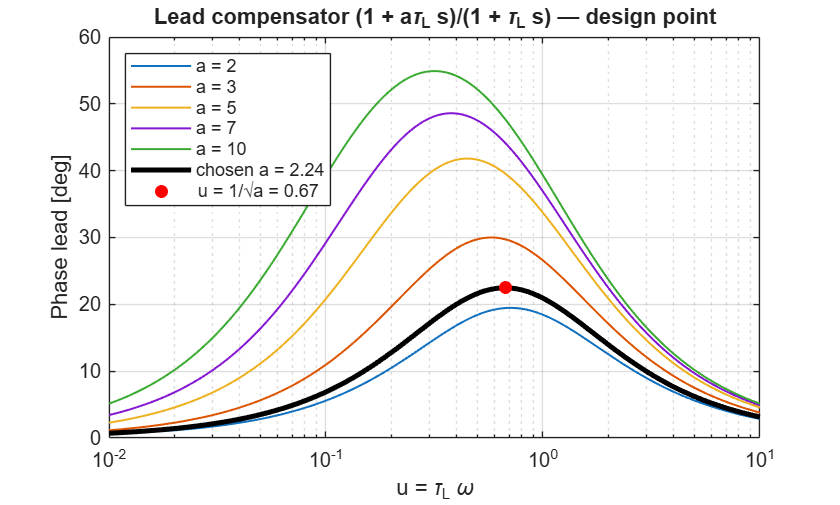


% graphical-method chart (as produced by LeadLag.m) with the chosen point
u = logspace(-2, 1, 400);
aList = [2 3 5 7 10];
figure
semilogx(u, rad2deg(angle((1 + 1j*aList'.*u)./(1 + 1j*u))), LineWidth=1); hold on
plot(u, rad2deg(angle((1 + 1j*lead.a*u)./(1 + 1j*u))), "k", LineWidth=2.5)
uStar = 1/sqrt(lead.a);
plot(uStar, asind((lead.a - 1)/(lead.a + 1)), "ro", MarkerFaceColor="r"); hold off
grid on; xlabel("u = \tau_L \omega"); ylabel("Phase lead [deg]")
legend([compose("a = %g", aList), sprintf("chosen a = %.2f", lead.a), sprintf("u = 1/\\surda = %.2f", uStar)], Location="northwest")
title("Lead compensator (1 + a\tau_L s)/(1 + \tau_L s) — design point")

### Bode shift produced by the lead

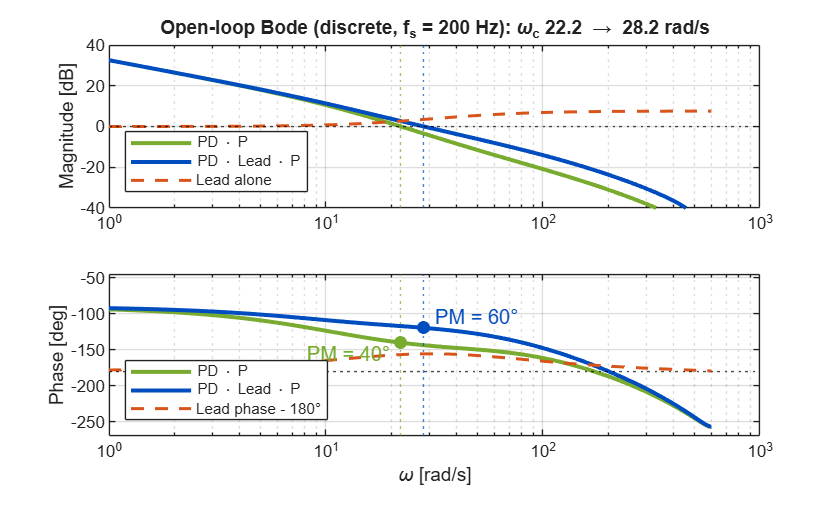

w = logspace(0, log10(0.95*pi/Ts), 600);
[mPD, pPD] = bode(Lpd, w);   mPD = 20*log10(squeeze(mPD)); pPD = squeeze(pPD);
[mLL, pLL] = bode(Lll, w);   mLL = 20*log10(squeeze(mLL)); pLL = squeeze(pLL);
[mC, pC] = bode(Clead, w);   mC = 20*log10(squeeze(mC));   pC = squeeze(pC);
pPD = pPD - 360*round((pPD(1) + 90)/360); pLL = pLL - 360*round((pLL(1) + 90)/360);
cPD = [0.47 0.67 0.19]; cLL = [0.00 0.30 0.75]; cC = [0.85 0.33 0.10];
figure
tiledlayout(2, 1, TileSpacing="compact")
nexttile
semilogx(w, mPD, Color=cPD, LineWidth=2); hold on
semilogx(w, mLL, Color=cLL, LineWidth=2)
semilogx(w, mC, "--", Color=cC, LineWidth=1.5)
yline(0, "k:"); xline(wcPD, ":", Color=cPD); xline(wcLL, ":", Color=cLL); hold off
grid on; ylabel("Magnitude [dB]"); ylim([-40 40])
legend("PD \cdot P", "PD \cdot Lead \cdot P", "Lead alone", Location="southwest")
title(sprintf("Open-loop Bode (discrete, f_s = %g Hz): \\omega_c %.1f \\rightarrow %.1f rad/s", fs, wcPD, wcLL))
nexttile
semilogx(w, pPD, Color=cPD, LineWidth=2); hold on
semilogx(w, pLL, Color=cLL, LineWidth=2)
semilogx(w, pC - 180, "--", Color=cC, LineWidth=1.5)
yline(-180, "k:"); xline(wcPD, ":", Color=cPD); xline(wcLL, ":", Color=cLL)
plot(wcPD, -180 + PMpd, "o", Color=cPD, MarkerFaceColor=cPD)
plot(wcLL, -180 + PMll, "o", Color=cLL, MarkerFaceColor=cLL); hold off
text(wcPD, -180 + PMpd, sprintf("PM = %.0f°  ", PMpd), Color=cPD, HorizontalAlignment="right", VerticalAlignment="top")
text(wcLL, -180 + PMll, sprintf("  PM = %.0f°", PMll), Color=cLL, VerticalAlignment="bottom")
grid on; ylabel("Phase [deg]"); xlabel("\omega [rad/s]"); ylim([-270 -45])
legend("PD \cdot P", "PD \cdot Lead \cdot P", "Lead phase - 180°", Location="southwest")

## 3. Experiment A — step responses: PD vs. PD + Lead

The pulse generator gives a 1 rad square wave (period 4 s). The run sets the model's workspace variables `Kp`, `Kd`, `T1` and `T2`. The PD-only run uses $T_1 = T_2$, which makes the Lead-Lag block a unity gain. In hardware mode each run is built and deployed.

 
stepStop = 7;
Tneutral = 0.01;                                  % T1 = T2 -> Lead-Lag block = 1
stepPD = runLeadLag(runMode, llModel, "pulse", stepStop, Ts, Kp, Kd, Tneutral, Tneutral, N);
stepLL = runLeadLag(runMode, llModel, "pulse", stepStop, Ts, Kp, Kd, T1lead, T2lead, N);
assignin("base", "T1", T1lead); assignin("base", "T2", T2lead);  % leave the designed lead in the model variables

tA = stepPD.time; rA = stepPD.signals.values(:,1);
ySimPD = simLoop(Pd, Cpd, rA);
ySimLL = simLoop(Pd, Cpd*Clead, stepLL.signals.values(:,1));
yPD = stepPD.signals.values(:,2); yLL = stepLL.signals.values(:,2);
[osPD, tpPD] = firstStepMetrics(tA, yPD);         [osLL, tpLL] = firstStepMetrics(stepLL.time, yLL);
[osSPD, tpSPD] = firstStepMetrics(tA, ySimPD);    [osSLL, tpSLL] = firstStepMetrics(stepLL.time, ySimLL);
fprintf("PD        : %s OS = %4.1f %%, Tp = %.3f s | simulated OS = %4.1f %%, Tp = %.3f s\n", lower(measLabel), osPD, tpPD, osSPD, tpSPD);

PD        : emulated OS = 20.8 %, Tp = 0.140 s | simulated OS = 25.9 %, Tp = 0.155 s


fprintf("PD + Lead : %s OS = %4.1f %%, Tp = %.3f s | simulated OS = %4.1f %%, Tp = %.3f s\n", lower(measLabel), osLL, tpLL, osSLL, tpSLL);

PD + Lead : emulated OS =  0.3 %, Tp = 0.355 s | simulated OS =  1.2 %, Tp = 0.195 s


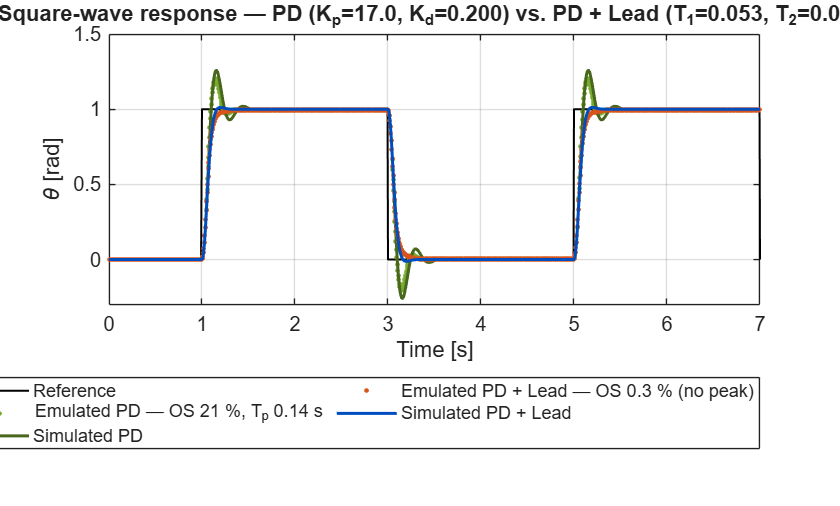


figure
plot(tA, rA, "k", LineWidth=1, DisplayName="Reference"); hold on
plot(tA, yPD, ".", MarkerSize=7, Color=cPD, DisplayName=measLabel + " PD — " + metricsLabel(osPD, tpPD))
plot(tA, ySimPD, "-", LineWidth=1.5, Color=0.6*cPD, DisplayName="Simulated PD")
plot(stepLL.time, yLL, ".", MarkerSize=7, Color=cC, DisplayName=measLabel + " PD + Lead — " + metricsLabel(osLL, tpLL))
plot(stepLL.time, ySimLL, "-", LineWidth=1.5, Color=cLL, DisplayName="Simulated PD + Lead"); hold off
grid on; legend(Location="southoutside", NumColumns=2)
xlim([0 stepStop]); ylim([-0.3 1.5])
title(sprintf("Square-wave response — PD (K_p=%.1f, K_d=%.3f) vs. PD + Lead (T_1=%.3f, T_2=%.3f)", Kp, Kd, T1lead, T2lead))
xlabel("Time [s]"); ylabel("\theta [rad]")

## 4. Experiment B — frequency responses: PD vs. PD + Lead

Chirp reference, 1 rad from 0.1 to 5 Hz over 30 s, for both controllers. The closed-loop frequency response is estimated from each recording with `spafdr` and compared with the model. The lead flattens the resonant peak, which is the closed-loop view of the added phase margin. At the top of the sweep the 12 V supply limit is reached, so the measured response falls below the linear model there.

 
chirpT = 30;
chirpPD = runLeadLag(runMode, llModel, "chirp", chirpT, Ts, Kp, Kd, Tneutral, Tneutral, N);
chirpLL = runLeadLag(runMode, llModel, "chirp", chirpT, Ts, Kp, Kd, T1lead, T2lead, N);
assignin("base", "T1", T1lead); assignin("base", "T2", T2lead);  % leave the designed lead in the model variables

wf = logspace(log10(2*pi*0.1), log10(2*pi*5), 150);
frPD = spafdr(iddata(chirpPD.signals.values(:,2), chirpPD.signals.values(:,1), Ts), [], wf);
frLL = spafdr(iddata(chirpLL.signals.values(:,2), chirpLL.signals.values(:,1), Ts), [], wf);
[mEPD, pEPD] = bode(frPD, wf); [mELL, pELL] = bode(frLL, wf);
[mMPD, pMPD] = bode(feedback(Lpd, 1), wf); [mMLL, pMLL] = bode(feedback(Lll, 1), wf);
db = @(m) 20*log10(squeeze(m));
fprintf("Closed-loop resonant peak: PD %.1f dB (model %.1f dB), PD + Lead %.1f dB (model %.1f dB)\n", ...
    max(db(mEPD)), max(db(mMPD)), max(db(mELL)), max(db(mMLL)));

Closed-loop resonant peak: PD 2.7 dB (model 3.5 dB), PD + Lead 0.5 dB (model 0.8 dB)


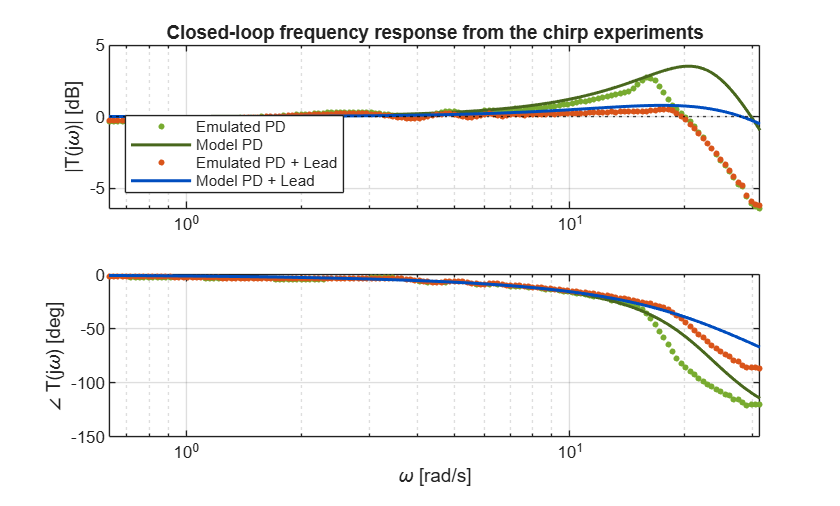


figure
tiledlayout(2, 1, TileSpacing="compact")
nexttile
semilogx(wf, db(mEPD), ".", Color=cPD, MarkerSize=9); hold on
semilogx(wf, db(mMPD), "-", Color=0.6*cPD, LineWidth=1.5)
semilogx(wf, db(mELL), ".", Color=cC, MarkerSize=9)
semilogx(wf, db(mMLL), "-", Color=cLL, LineWidth=1.5); yline(0, "k:"); hold off
grid on; ylabel("|T(j\omega)| [dB]")
legend(measLabel + " PD", "Model PD", measLabel + " PD + Lead", "Model PD + Lead", Location="southwest")
title("Closed-loop frequency response from the chirp experiments")
nexttile
semilogx(wf, squeeze(pEPD), ".", Color=cPD, MarkerSize=9); hold on
semilogx(wf, squeeze(pMPD), "-", Color=0.6*cPD, LineWidth=1.5)
semilogx(wf, squeeze(pELL), ".", Color=cC, MarkerSize=9)
semilogx(wf, squeeze(pMLL), "-", Color=cLL, LineWidth=1.5); hold off
grid on; ylabel("\angle T(j\omega) [deg]"); xlabel("\omega [rad/s]")

## Local functions

function [T1, T2, info] = designLead(L, PMtarget, Ts)
% Lead design on the discrete open loop L: iterate the extra phase margin until the
% compensated loop (Forward-Euler lead, as in the Simulink block) meets PMtarget.
[~, PM0] = margin(L);
w = logspace(-1, log10(0.95*pi/Ts), 4000);
magL = squeeze(abs(freqresp(L, w)));
extra = 5;
for it = 1:30
    phi = min(max(PMtarget - PM0 + extra, 1), 70);
    a = (1 + sind(phi))/(1 - sind(phi));
    k = find(magL < 1/sqrt(a), 1);                % new crossover: |L| = 1/sqrt(a)
    wm = w(k);
    tauL = max(1/(wm*sqrt(a)), Ts);               % sample-rate constraint T2 >= Ts
    T2 = tauL; T1 = a*tauL;
    [~, PM] = margin(L*leadFE(T1, T2, Ts));
    if abs(PM - PMtarget) < 0.5, break, end
    extra = extra + 0.8*(PMtarget - PM);
end
info = struct("a", a, "phi", phi, "wm", wm, "PM", PM, "iterations", it);
end

function str = metricsLabel(os, tp)
if os < 2, str = sprintf("OS %.1f %% (no peak)", os); else, str = sprintf("OS %.0f %%, T_p %.2f s", os, tp); end
end

function C = leadFE(T1, T2, Ts)
% Lead-Lag (Discrete or Continuous) block, discrete form = Forward Euler: s -> (z-1)/Ts
z = tf("z", Ts);
C = (1 + T1*(z - 1)/Ts)/(1 + T2*(z - 1)/Ts);
end

function y = simLoop(Pd, Cd, r)
% Discrete closed loop with the +/-12 V supply limit (minus the 0.35 V friction feed-forward).
[Ap, Bp, Cp] = ssdata(ss(Pd)); [Ac, Bc, Cc, Dc] = ssdata(ss(Cd));
xp = zeros(size(Ap, 1), 1); xc = zeros(size(Ac, 1), 1); uLim = 12 - 0.35;
y = zeros(size(r));
for k = 1:numel(r)
    y(k) = Cp*xp;
    e = r(k) - y(k);
    u = min(max(Cc*xc + Dc*e, -uLim), uLim);
    xc = Ac*xc + Bc*e;
    xp = Ap*xp + Bp*u;
end
end

function [os, tp] = firstStepMetrics(t, y)
% Overshoot [%] and peak time [s] of the first rising edge at t = 1 s.
win = t >= 1 & t < 3;
yss = mean(y(t > 2.6 & t < 3));
[ym, i] = max(y(win)); tw = t(win);
os = 100*(ym - yss)/yss; tp = tw(i) - 1;
end

function sd = runLeadLag(runMode, mdl, refType, stopTime, Ts, Kp, Kd, T1, T2, N)
% Configure and run one experiment on the Lead-Lag model (hardware) or on the emulator.
if runMode == "hw"
    for v = ["Kp" "Kd" "T1" "T2"]                 % the model reads these from the base workspace
        assignin("base", v, eval(v));
    end
    assignin("base", "sampleRate", Ts);
    mdl = char(mdl);
    load_system(mdl);
    set_param(mdl, FixedStep=num2str(Ts));
    if refType == "pulse", swPos = "1"; else, swPos = "0"; end
    set_param([mdl '/Manual Switch'], sw=swPos);    % "1" = upper input = Pulse, "0" = lower input = Chirp
    if refType == "chirp"
        set_param([mdl '/Chirp Signal'], f1="0.1", f2="5", T=num2str(stopTime));
    end
    sd = runOnHexaMotor(mdl, stopTime);
else
    z = tf("z", Ts);
    Cd = (Kp + Kd*N/(1 + N*Ts/(z - 1)))*leadFE(T1, T2, Ts);
    sd = virtualHexaMotor(refType, Ts, stopTime, Cd);
end
end

function showLiveView(mdl, stopTime)
% Open the model diagram and its Scope so the audience sees the running model and the live
% external-mode response; the Scope time span covers the whole run.
open_system(mdl);
scopes = find_system(mdl, SearchDepth=1, BlockType="Scope");
for i = 1:numel(scopes)
    cfg = get_param(scopes{i}, "ScopeConfiguration");
    cfg.TimeSpan = num2str(stopTime);
    cfg.OpenAtSimulationStart = true;
    cfg.Visible = true;
end
drawnow
end

function sd = runOnHexaMotor(mdl, stopTime)
% Build, deploy and run a model on the HexaMotor in external mode (the "Monitor & Tune" button),
% wait for it to stop and return the Scope's logged ScopeData.
mdl = char(mdl);
set_param(mdl, StopTime=num2str(stopTime), SimulationMode="external");
showLiveView(mdl, stopTime);                      % model diagram + live Scope during the run
evalin("base", "clear ScopeData");
fprintf("Building, deploying and running %s on the HexaMotor ...\n", mdl);
set_param(mdl, SimulationCommand="start");
t0 = tic;
while toc(t0) < 600 + 3*stopTime
    pause(0.5); drawnow
    if strcmp(get_param(mdl, "SimulationStatus"), "stopped") && evalin("base", "exist('ScopeData','var')")
        break
    end
end
if ~evalin("base", "exist('ScopeData','var')")
    error("No ScopeData received from %s. Check the USB cable, power switch and the Scope logging settings.", mdl);
end
sd = evalin("base", "ScopeData");
fprintf("Done: %d samples recorded.\n", numel(sd.time));
end

function sd = virtualHexaMotor(refType, Ts, stopTime, Cd)
% Nonlinear stand-in for the HexaMotor position loop with an arbitrary discrete controller Cd.
kmT = 2.42; tauT = 0.0705;        % true first-order motor [rad/s/V], [s]
Vstick = 0.32; Vcoul = 0.28;      % static / kinetic friction, voltage-equivalent [V]
Vcomp = 0.35;                     % friction feed-forward in the model [V]
enc = 2*pi/979.62;                % encoder resolution at the gearbox output [rad]
t = (0:round(stopTime/Ts))'*Ts;
if refType == "chirp"             % Simulink Chirp Signal: f(t) = f1 + (f2-f1) t/T
    f1 = 0.1; f2 = 5;
    r = sin(2*pi*(f1 + (f2 - f1)/(2*stopTime)*t).*t);
else                              % Pulse: 1 rad, 4 s period, 2 s width, 1 s delay
    r = double(t >= 1 & mod(t - 1, 4) < 2);
end
[Ac, Bc, Cc, Dc] = ssdata(ss(Cd)); xc = zeros(size(Ac, 1), 1);
nSub = 20; dt = Ts/nSub;
theta = 0; w = 0;
y = zeros(size(t));
for k = 1:numel(t)
    y(k) = enc*round(theta/enc);
    e = r(k) - y(k);
    u = Cc*xc + Dc*e;
    xc = Ac*xc + Bc*e;
    v = u + Vcomp*sign(u);
    v = round(min(max(v, -12), 12)/12*255)*12/255;   % 8-bit PWM, 12 V supply
    for j = 1:nSub
        if w == 0 && abs(v) <= Vstick, continue, end
        dir = sign(w); if dir == 0, dir = sign(v); end
        wNew = w + dt*(kmT*(v - Vcoul*dir) - w)/tauT;
        if w ~= 0 && sign(wNew) ~= sign(w) && abs(v) <= Vstick, wNew = 0; end
        theta = theta + dt*(w + wNew)/2;
        w = wNew;
    end
end
sd.time = t;
sd.signals.values = [r y];
end